# Popular datasets

## Diamonds Dataset

diamonds = readtable('diamonds.csv');
% summary(diamonds)

/bin/bash: -c: line 0: syntax error near unexpected token `diamonds'
/bin/bash: -c: line 0: ` summary(diamonds)'


head(diamonds)

    Var1    carat         cut         color    clarity     depth    table    price     x       y       z  
    ____    _____    _____________    _____    ________    _____    _____    _____    ____    ____    ____

     1      0.23     {'Ideal'    }    {'E'}    {'SI2' }    61.5      55       326     3.95    3.98    2.43
     2      0.21     {'Premium'  }    {'E'}    {'SI1' }    59.8      61       326     3.89    3.84    2.31
     3      0.23     {'Good'     }    {'E'}    {'VS1' }    56.9      65       327     4.05    4.07    2.31
     4      0.29     {'Premium'  }    {'I'}    {'VS2' }    62.4      58       334      4.2

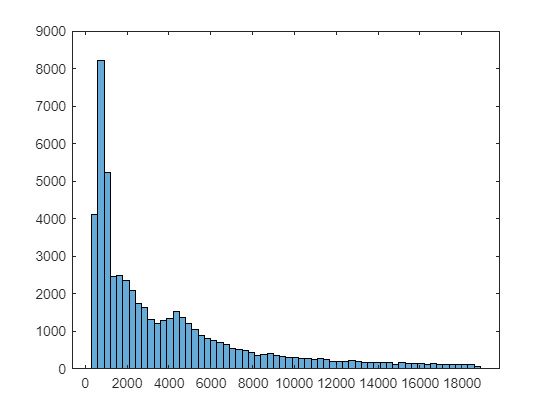

figure(1)
histogram(diamonds.price)

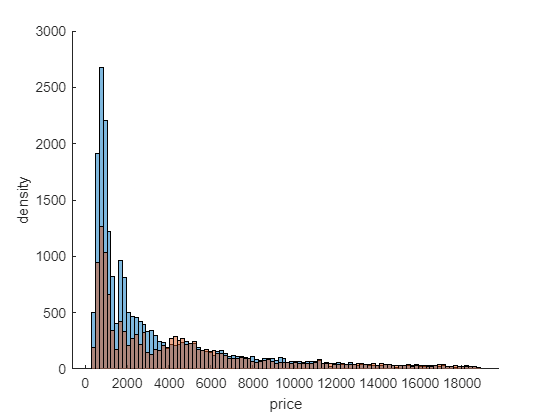


figure(2)
clf
hold on
h1 = histogram(diamonds.price(strcmp(diamonds.cut,'Ideal')), 100);
h2 = histogram(diamonds.price(strcmp(diamonds.cut,'Premium')), 100);
set(h1,'facealpha',0.5);
set(h2,'facealpha',0.5);
xlabel('price')
ylabel('density')
hold off

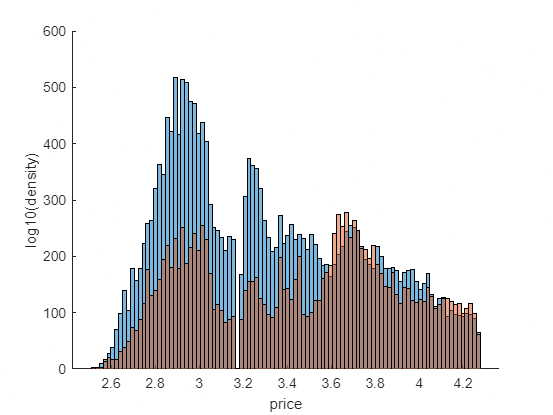


figure(3)
clf
hold on
h1 = histogram(log10(diamonds.price(strcmp(diamonds.cut,'Ideal'))), 100);
h2 = histogram(log10(diamonds.price(strcmp(diamonds.cut,'Premium'))), 100);
set(h1,'facealpha',0.5);
set(h2,'facealpha',0.5);
xlabel('price')
ylabel('log10(density)')
hold off

## Artificial dataset for adjustment

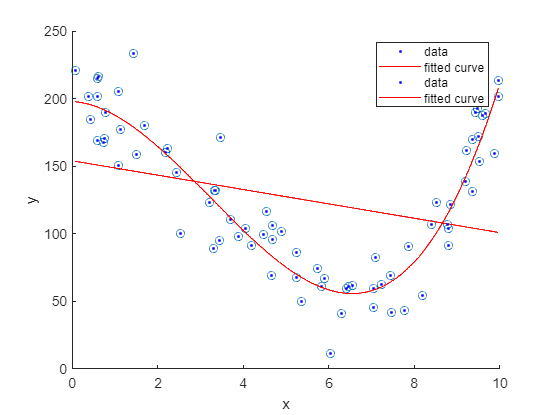

x=(rand(75,1))*10;
x=sort(x);
y=200+x.^3 - 10*x.^2 + x + randn(75,1)*20;
f1=fit(x,y,'poly1');
f3=fit(x,y,'poly3');

figure(4)
clf
hold on
plot(x,y,'o')
plot(f1,x,y)
plot(f3,x,y)
hold off

## Cars Dataset

cars = readtable('mtcars.csv');
summary(cars)

Variables:

    model: 32×1 cell array of character vectors

    mpg: 32×1 double

        Values:

            Min         10.4  
            Median      19.2  
            Max         33.9  

    cyl: 32×1 double

        Values:

            Min          4    
            Median       6    
            Max          8    

    disp: 32×1 double

        Values:

            Min         71.1  
            Median     196.3  
            Max          472  

    hp: 32×1 double

        Values:

            Min          52   
            Median      123   
            Max         335   

    drat: 32×1 double

        Values:

            Min         2.76  
            Median     3.695  
            Max         4.93  

    wt: 32×1 double

        Values:

            Min        1.513  
            Median     3.325  
            Max        5.424  

    qsec

[conttbl,chi2,p,labels] = crosstab(cars.cyl, cars.gear)

conttbl =      1     8     2
     2     4     1
    12     0     2


chi2 = 18.0364

p = 0.0012

labels = 3×2 cell array
    {'4'}    {'3'}
    {'6'}    {'4'}
    {'8'}    {'5'}


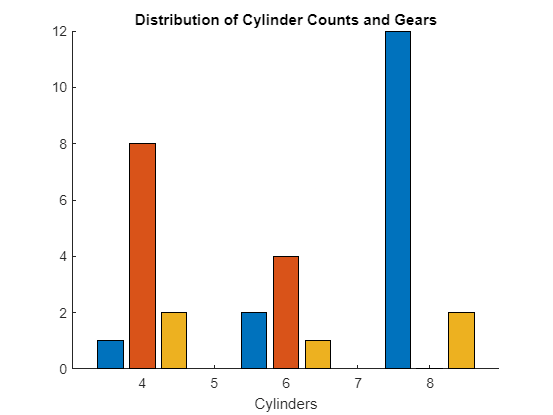


figure(5)
clf
hold on
bar([4 6 8],conttbl)
title('Distribution of Cylinder Counts and Gears')
xlabel('Cylinders')
hold off


load carsmall
X = [Acceleration Displacement Horsepower MPG Weight];
color = lines(3)

color =          0    0.4470    0.7410
    0.8500    0.3250    0.0980
    0.9290    0.6940    0.1250


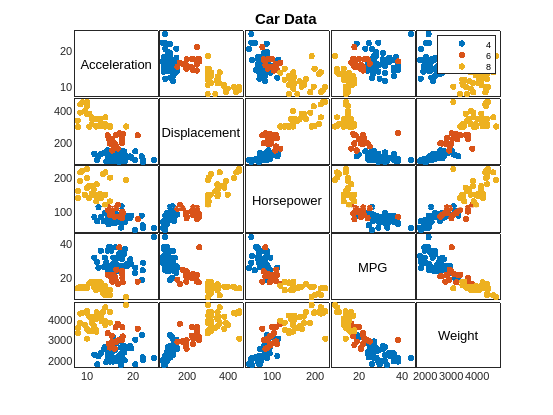

xnames = {'Acceleration', 'Displacement', 'Horsepower', 'MPG', 'Weight'};
figure(6)
[h, ax] =gplotmatrix(X,[],Cylinders,color,[],[],[],'variable',xnames);
title('Car Data')

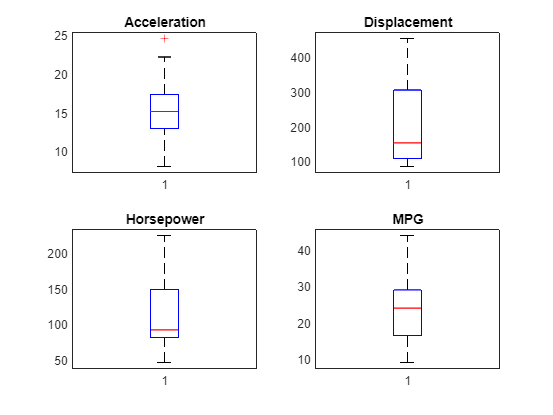


figure(7)
clf
hold on
subplot(2,2,1);
boxplot(X(:,1))
title(xnames(1))
subplot(2,2,2);
boxplot(X(:,2))
title(xnames(2))
subplot(2,2,3);
boxplot(X(:,3))
title(xnames(3))
subplot(2,2,4);
boxplot(X(:,4))
title(xnames(4))
hold off

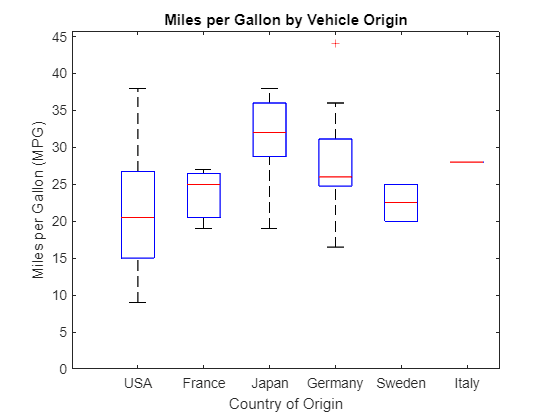


figure(8)
clf
hold on
boxplot(MPG,Origin)
title('Miles per Gallon by Vehicle Origin')
xlabel('Country of Origin')
ylabel('Miles per Gallon (MPG)')
hold off

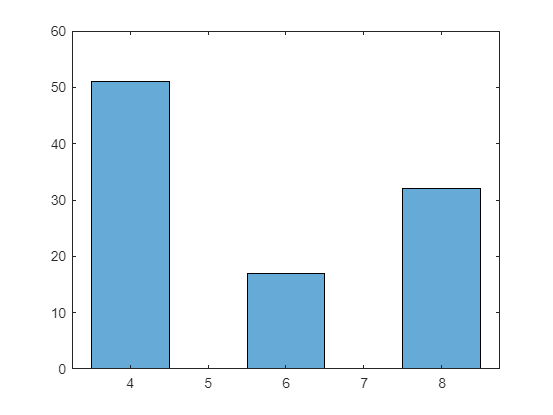


figure(9)
histogram(Cylinders)

[C,ia,ic] = unique(Cylinders)

C =      4
     6
     8


ia =     11
    22
     1


ic =      3
     3
     3
     3
     3
     3
     3
     3
     3
     3


a_counts = accumarray(ic,1);
value_counts = [C, a_counts]

value_counts =      4    51
     6    17
     8    32


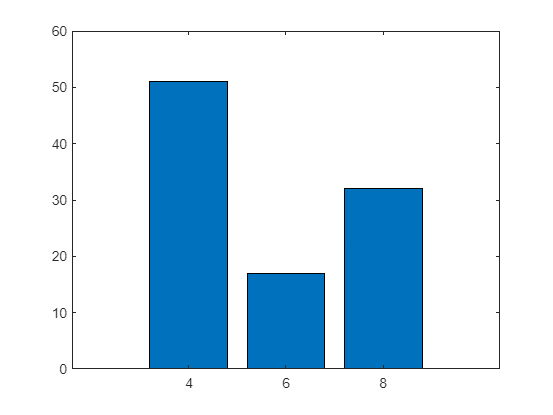

bar(C,a_counts)

## Household Income ZIP

zipIncome = readtable('zipIncome.csv');
class(zipIncome)

ans = 'table'

zipIncome.Properties

ans =   TableProperties with properties:

             Description: ''
                UserData: []
          DimensionNames: {'Row'  'Variables'}
           VariableNames: {'MeanEducation'  'MeanHouseholdIncome'  'Zip1'}
    VariableDescriptions: {}
           VariableUnits: {}
      VariableContinuity: []
                RowNames: {}
        CustomProperties: No custom properties are set.
      Use addprop and rmprop to modify CustomProperties.


head(zipIncome)

    MeanEducation    MeanHouseholdIncome    Zip1
    _____________    ___________________    ____

       10.868               19109            0  
       11.063               21592            0  
       10.789               20006            0  
       10.062               12013            0  
       11.156               19189            0  
       10.368               16687            0  
       11.148               20752            0  
       10.725               20478            0  



size(zipIncome)

ans =        32038           3


s=summary(zipIncome)

s = struct with fields:
          MeanEducation: [1×1 struct]
    MeanHouseholdIncome: [1×1 struct]
                   Zip1: [1×1 struct]


s.MeanHouseholdIncome

ans = struct with fields:
           Size: [32038 1]
           Type: 'double'
    Description: ''
          Units: ''
     Continuity: []
            Min: 0
         Median: 4.4163e+04
            Max: 250000
     NumMissing: 0


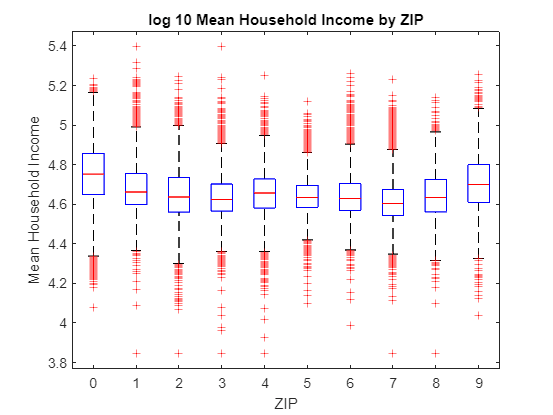


figure(10)
boxplot(log10(zipIncome.MeanHouseholdIncome),zipIncome.Zip1)
title('log 10 Mean Household Income by ZIP')
xlabel('ZIP')
ylabel('Mean Household Income')

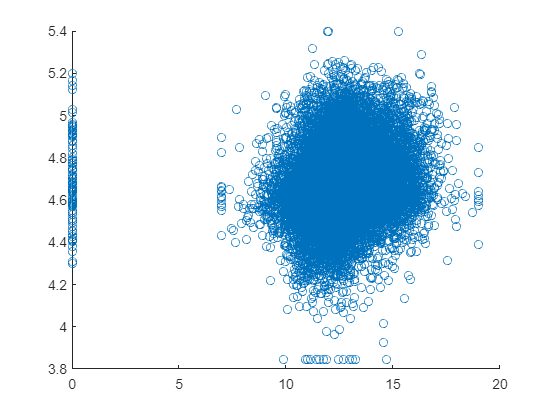


x=zipIncome.MeanEducation;
y=zipIncome.MeanHouseholdIncome;
y=log10(y);
y=y(~isinf(y));
x=x(~isinf(y));
scatter(x,y)

[fitobj,gof,output] = fit(x,y,'poly1')

fitobj =      Linear model Poly1:
     fitobj(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =     0.01319  (0.01209, 0.0143)
       p2 =       4.496  (4.482, 4.51)

gof = struct with fields:
           sse: 625.4542
       rsquare: 0.0168
           dfe: 31887
    adjrsquare: 0.0168
          rmse: 0.1401


output = struct with fields:
        numobs: 31889
      numparam: 2
     residuals: [31889×1 double]
      Jacobian: [31889×2 double]
      exitflag: 1
     algorithm: 'QR factorization and solve'
    iterations: 1


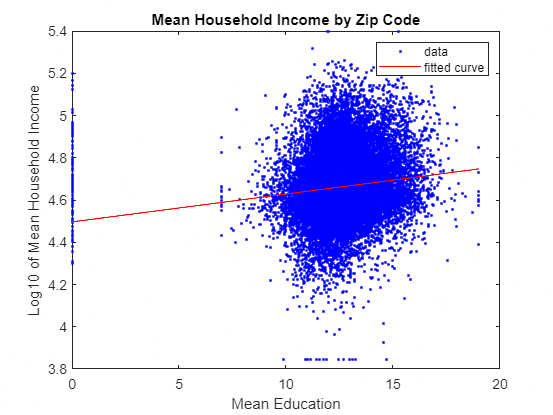

figure(11)
plot(fitobj,x,y)
title("Mean Household Income by Zip Code")
xlabel("Mean Education")
ylabel("Log10 of Mean Household Income")

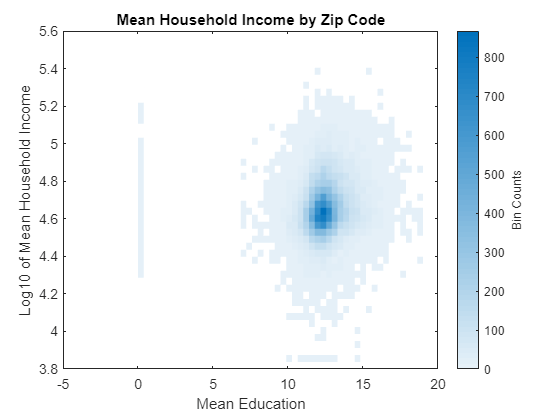


figure(12)
binscatter(x,y)
title("Mean Household Income by Zip Code")
xlabel("Mean Education")
ylabel("Log10 of Mean Household Income")

## Fisher Dataset

load fisheriris
measnames = {'SepalLengthCm' 'SepalWidthCm' 'PetalLengthCm' 'PetalWidthCm'};
iris=table(meas(:,1),meas(:,2),meas(:,3),meas(:,4),'VariableNames',measnames);
iris.species=species;
head(iris)

    SepalLengthCm    SepalWidthCm    PetalLengthCm    PetalWidthCm     species  
    _____________    ____________    _____________    ____________    __________

         5.1             3.5              1.4             0.2         {'setosa'}
         4.9               3              1.4             0.2         {'setosa'}
         4.7             3.2              1.3             0.2         {'setosa'}
         4.6             3.1              1.5             0.2         {'setosa'}
           5             3.6              1.4             0.2         {'setosa'}
         5.4             3.9              1.7             0.4         {'setosa'}
         4.6             3.4              1.4             0.3         {'setosa'}
           5             3.4              1.5             0.2         {'setosa'}



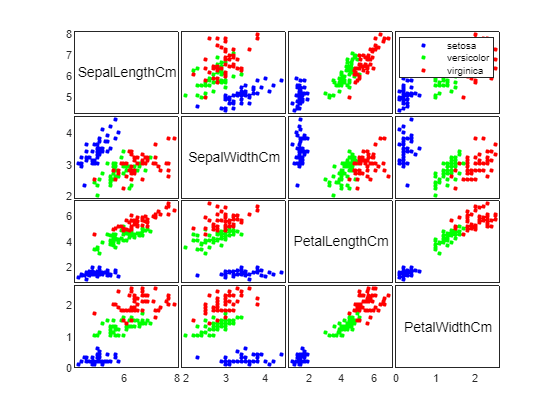

ans =   Text (PetalWidthCm) with properties:

                 String: 'PetalWidthCm'
               FontSize: 10
             FontWeight: 'normal'
               FontName: 'Helvetica'
                  Color: [0 0 0]
    HorizontalAlignment: 'center'
               Position: [0.5000 0.5000 -0.1000]
                  Units: 'normalized'

  Show all properties



figure(13)
gplotmatrix(meas,[],species,[],[],[],[],'variable',measnames)

## Air Passengers Dataset

airpassengers = readtable('AirPassengers.csv');
summary(airpassengers)

Variables:

    Month: 144×1 cell array of character vectors

    Passengers: 144×1 double

        Values:

            Min          104  
            Median     265.5  
            Max          622  



head(airpassengers)

       Month       Passengers
    ___________    __________

    {'1949-01'}       112    
    {'1949-02'}       118    
    {'1949-03'}       132    
    {'1949-04'}       129    
    {'1949-05'}       121    
    {'1949-06'}       135    
    {'1949-07'}       148    
    {'1949-08'}       148    



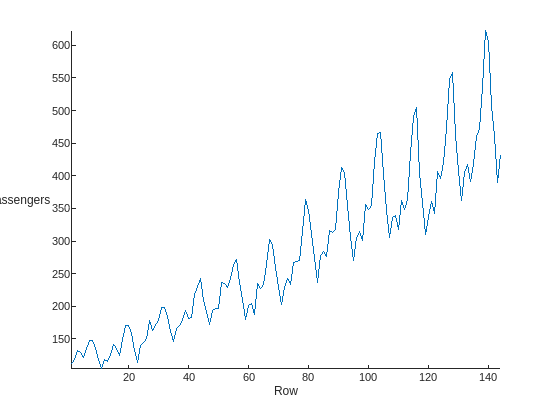


figure(14)
stackedplot(airpassengers)

## Incomes

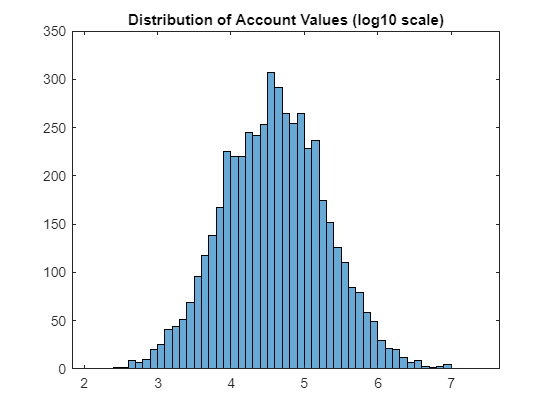

figure(15)
income = lognrnd(log(40000),log(5),5000,1);
histogram(log10(income))
title("Distribution of Account Values (log10 scale)")

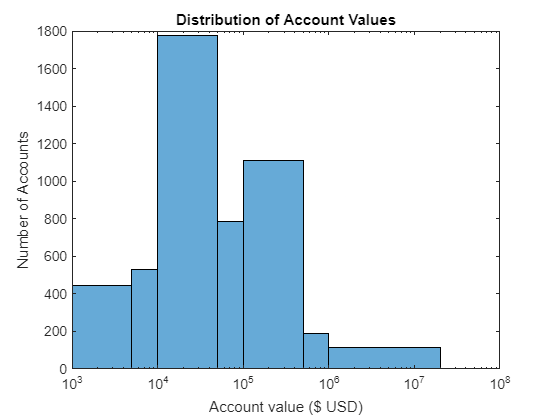


figure(16)
edges=[0, 1000, 5000, 10000, 50000, 100000, 5e5, 1e6, 2e7];
histogram(income,edges);
set(gca, 'xscale', 'log')
title("Distribution of Account Values")
xlabel("Account value ($ USD)")
ylabel("Number of Accounts")